# Obliczanie całek

Aby mieć dokładne wyniki włączamy pokazywanie większej niż zwykle liczby cyfr znaczących.

format long

Definiujemy funkcję Gaussa [funkcję Gaussa](https://pl.wikipedia.org/wiki/Rozk%C5%82ad_normalny) - tu jest wzór napisany w LaTeX, czyli ilustracja nie coś co naprawdę się liczy


$$f(x, x_0, \sigma) =
\frac 1 {\sqrt {2 \pi} \sigma}
 \exp \bigg[ -\frac {(x-x_0)^2} {2 \sigma^2} \bigg]$$


gauss = @(x, x0, sigma) 1 / sqrt(2*pi) ./ sigma .* exp(- (x-x0).^2 / 2 ./ sigma.^2);

Interesuje nas pole powierzchni pod krzywą Gaussa w zakresie od -1 do +1, ogólniej od jakiegoś a do jakiegoś b. Zdefiniujemy też N jako liczbę punktów potrzebnych do wykresu i utworzymy x jako wektor wartości zmiennej niezależnej.

a = -3;  % dolna granica całkowania
b = +3;  % górna granica całkowania
N = 1500; % liczba punktów - w zasadzie tylko do wykresów
x = linspace(a, b, N);

Obliczenia chcemy przeprowadzić dla różnych wartości parametru $\sigma$.

sigma_values = [1/3; 1/2; 1; 2; 3]

sigma_values =    0.333333333333333
   0.500000000000000
   1.000000000000000
   2.000000000000000
   3.000000000000000


Zobaczmy wykresy - zrobimy je na jednym rysunku - nie musimy nawet do tego używać pętli for - zadziała magia obliczeń na wektorach i macierzach jaka jest w Matlabie.

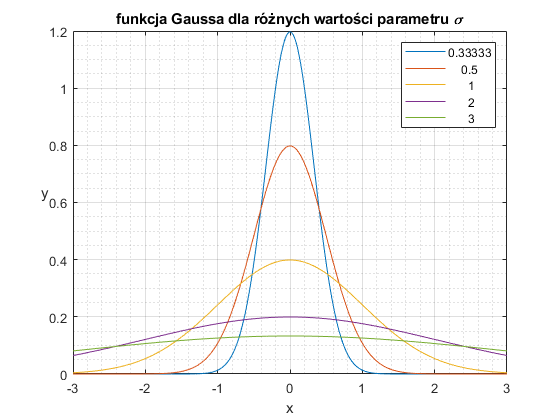

figure(1); 
clf; % clf nie zaszkodzi

y = gauss(x, 0, sigma_values);
plot(x, y);

grid minor;
grid on;
title('funkcja Gaussa dla różnych wartości parametru \sigma');
xlabel('x');
ylabel('y', 'rotation', 0); % rotation=0 ustawia linię tekstu równolegle do osi x
legend(num2str(sigma_values)); % num2str przekształca wektor wartości na tablicę napisów
hold all;

integral_values = arrayfun(@(sigma) integral(@(x) gauss(x, 0, sigma), a, b), sigma_values)

integral_values =    1.000000000000000
   0.999999998026825
   0.997300203936740
   0.866385597462284
   0.682689492137086


Zobaczmy teraz jak wygląda funkcja harmoniczna taka jak funkcja sinus. Dla częstotliwości freq można zapisać ją jako

f = @(x, freq) sin(2 * pi * freq * x);

Na przykład dla częstotliwości 10 otrzymamy dla a < x < b wykres jak poniżej:

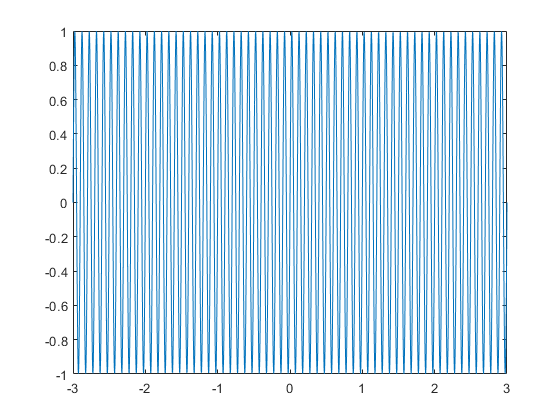

figure(2);
plot(x, f(x, 10));

Co się stanie gdy pomnożymy funkcję Gaussa przez funkcję sinus? Mamy dwie możliwości: mnożyć wartości i mnożyć funkcje.

Zobaczmy jak to będzie z mnożeniem wartości

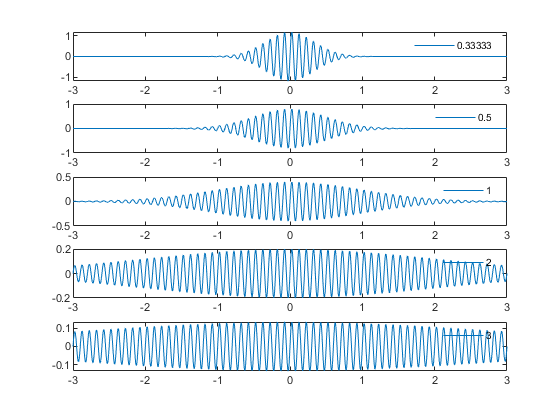

figure(3);

M = size(sigma_values, 1);
for i = 1 : M
    sigma = sigma_values(i);
    y_gauss = gauss(x, 0, sigma);
    y_sinus = f(x, 10);
    y(i,:) = y_gauss .* y_sinus;
    subplot(M, 1, i)
    plot(x, y(i,:));
    legend(num2str(sigma));
    legend('boxoff');    
end

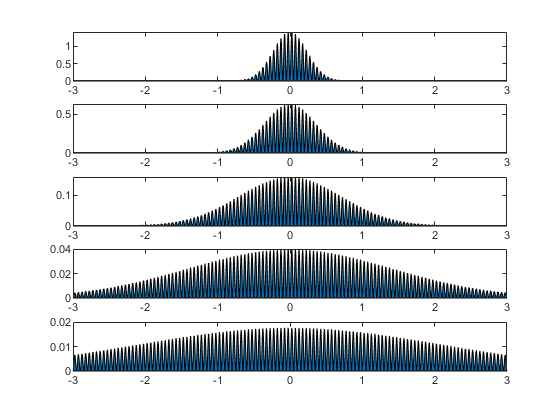

figure(4);
M = size(sigma_values, 1);
for i = 1 : M
    sigma = sigma_values(i);    
    subplot(M, 1, i)
    area(x, y(i,:).^2);
    % legend(num2str(sigma));
    % legend('boxoff');    
end

Oszacowanie pól powierzchni metodą trapezów:

for i = 1:M
    trapz(x, y(i,:).^2)
end

ans =    0.423142187660817


ans =    0.282094791773878


ans =    0.141044287530507


ans =    0.068133705973963


ans =    0.039620525508949


A teraz na funkcjach...

figure(5);

for i = 1:M
    sigma = sigma_values(i);
    y = gauss(x, 0, sigma) .* f(x, 10);
    subplot(M, 1, i);
    area(x, y.^2);
end

arrayfun(@(sigma) integral(@(x) (gauss(x, 0, sigma) .* f(x, 10)).^2, a, b), sigma_values)

ans =    0.423142187648079
   0.282094791772486
   0.141044287528497
   0.068133705866645
   0.039620525434959
